# **Práctica 5**

## **Problema 1: Ejemplo 6.2**

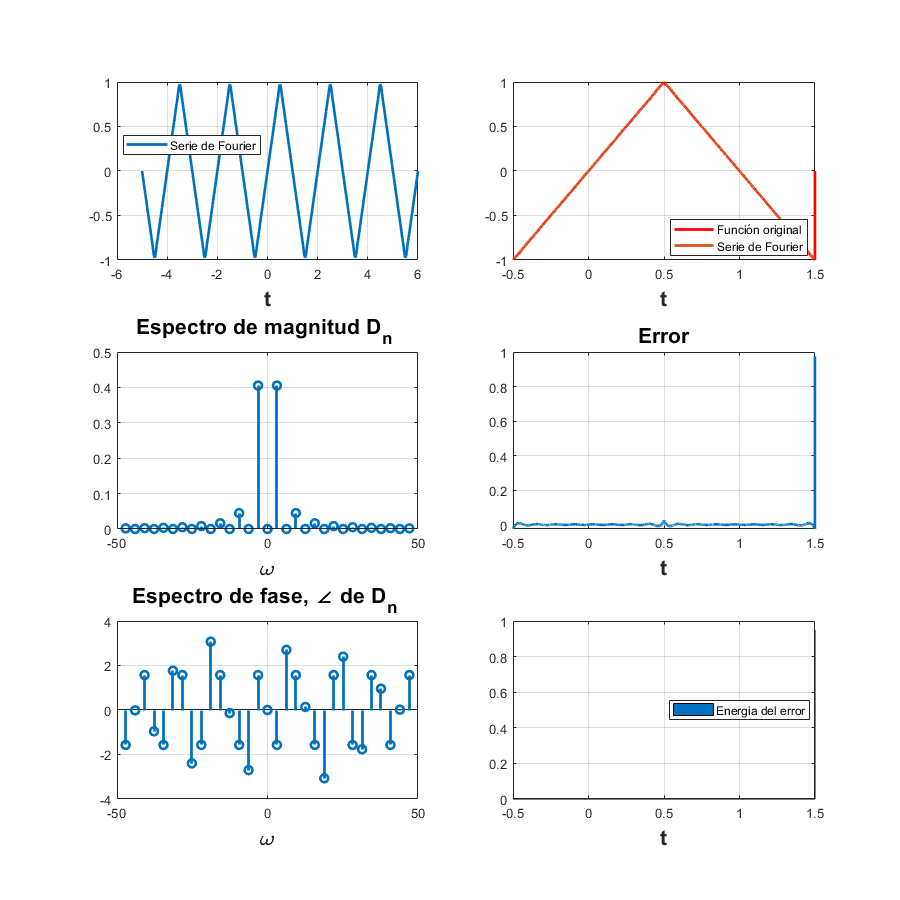

clear all; clc; close all;

T0 = 2;
w0= 2*pi/T0;
A = 1;
t0 = -1/2;
tf = 3/2;
f = @(t) (2*A*t).*(abs(t) <= 1/2) + 2*A*(1-t).*((1/2 < t) & (t < 3/2));
dn = @(n) integral(@(t) (1/T0).*exp(-n*w0*j*t).*f(t), -1/2, 3/2);
d0 = dn(0);
armo = 15;
a = -5;
b = 6;

sfc(t0,tf,dn,d0,f,armo,a,b);

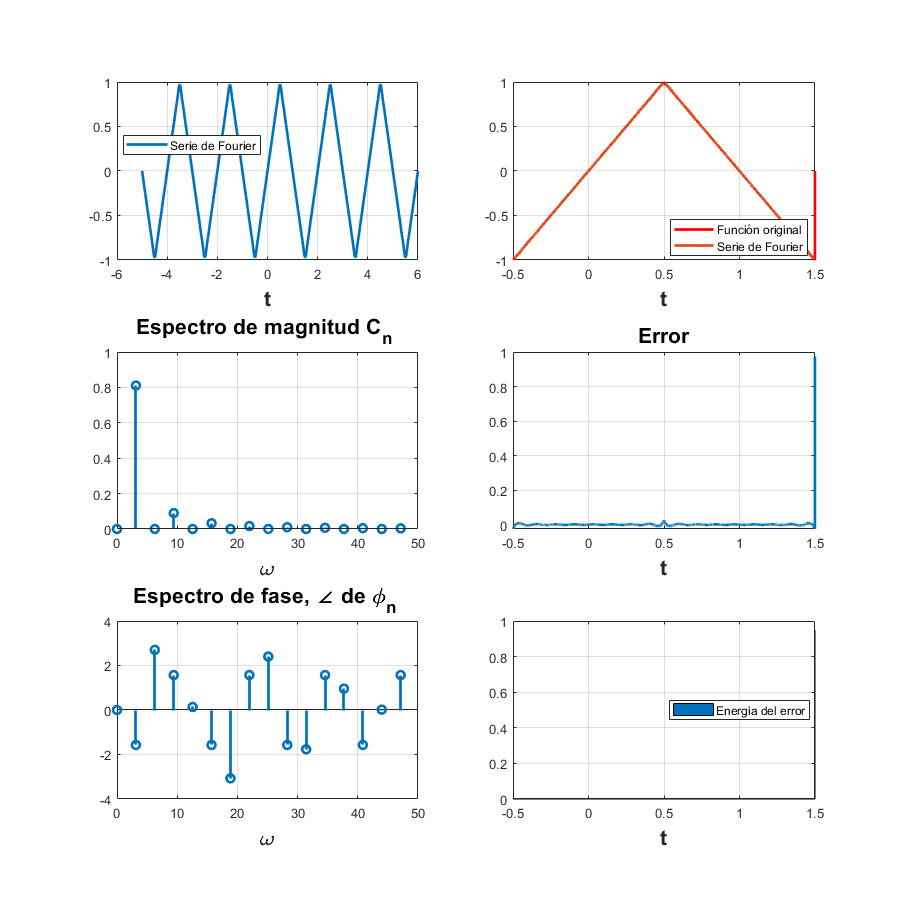


cn= @(n) 2*abs(dn(n));
phin = @(n) angle(dn(n));
c0 = abs(dn(0));
phi0 = angle(dn(0));

sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)

function sfc(t0,tf,dn,d0,f,armo,a,b)
% t0 el valor inicial para calcular la serie
% tf el valor final donde calcular la serie
% dn función de la fórmula de los dn
% f función original
% armo número de armonicos a utilizar en la gráfica
% a, b intevalo para realizar la grafica de la serie

w0=2*pi/(tf-t0);

sf=d0;
t=a:0.0001:b;

for n=1:armo
    sf=sf+dn(-n)*exp(w0*-n*t*j)+dn(n)*exp(w0*n*t*j);
end
figure (1)
hFig = figure(1);
set(hFig, 'Position', [0 0 900 900])
subplot(3,2,1)
plot(t,sf,'LineWidth',2)
grid on
legend('Serie de Fourier','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)

sf=d0;
t1=t0:0.0001:tf;

for n=1:armo
    sf=sf+dn(-n)*exp(w0*-n*t1*j)+dn(n)*exp(w0*n*t1*j);
end

subplot(3,2,2)
plot(t1,f(t1),'r','LineWidth',2)
grid on
hold on
plot(t1,sf,'LineWidth',2)
legend('Función original','Serie de Fourier ','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
nn=-armo:armo;
axis auto

subplot(3,2,4)
e=f(t1)-sf;
plot(t1,e,'LineWidth',2)
title('Error','FontWeight','bold','FontSize',16)
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

subplot(3,2,6)
e=f(t1)-sf;
area(t1,e.^2)
legend('Energia del error','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

absdn=zeros(1,length(nn));
cont=1;
for i =-armo:armo
    if i==0
        absdn(cont)=d0;
    end
    
    absdn(cont)=dn(i);
    cont=cont+1;
end

subplot(3,2,3)
stem(w0*nn,abs(absdn),'LineWidth',2)
title('Espectro de magnitud D_n ','FontWeight','bold','FontSize',16)
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

subplot(3,2,5) % % 
stem(w0*nn,angle(absdn),'LineWidth',2) % % 
title('Espectro de fase, \angle de D_n ','FontWeight','bold','FontSize',16) % % 
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

end

function sftc(t0,tf,cn, phin, c0, phi0,f,armo,a,b)
% t0 el valor inicial para calcular la serie
% tf el valor final donde calcular la serie
% dn función de la fórmula de los dn
% f función original
% armo número de armonicos a utilizar en la gráfica
% a, b intevalo para realizar la grafica de la serie

w0=2*pi/(tf-t0);

sf=c0*cos(phi0);
t=a:0.0001:b;

for n=1:armo
    sf=sf+cn(n)*cos(n*w0*t + phin(n));
end
figure (2)
hFig = figure(2);
set(hFig, 'Position', [0 0 900 900])
subplot(3,2,1)
plot(t,sf,'LineWidth',2)
grid on
legend('Serie de Fourier','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)

sf=c0*cos(phi0);
t1=t0:0.0001:tf;

for n=1:armo
    sf=sf+cn(n)*cos(n*w0*t1 + phin(n));
end

subplot(3,2,2)
plot(t1,f(t1),'r','LineWidth',2)
grid on
hold on
plot(t1,sf,'LineWidth',2)
legend('Función original','Serie de Fourier ','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
nn= 0:armo;
axis auto

subplot(3,2,4)
e=f(t1)-sf;
plot(t1,e,'LineWidth',2)
title('Error','FontWeight','bold','FontSize',16)
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

subplot(3,2,6)
e=f(t1)-sf;
area(t1,e.^2)
legend('Energia del error','Location','Best')
xlabel('t','FontWeight','bold','FontSize',16)
axis auto
grid on

abscn=zeros(1,length(nn));
cont=1;
for i =0:armo
    if i==0
        abscn(cont)=c0;
    end
    
    abscn(cont)=cn(i);
    cont=cont+1;
end

subplot(3,2,3)
stem(w0*nn,abs(abscn),'LineWidth',2)
title('Espectro de magnitud C_n ','FontWeight','bold','FontSize',16)
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

angphin=zeros(1,length(nn));
cont=1;
for i =0:armo
    if i==0
        angphin(cont)=phi0;
    end
    
    angphin(cont)=phin(i);
    cont=cont+1;
end

subplot(3,2,5) % % 
stem(w0*nn, angphin,'LineWidth',2) % % 
title('Espectro de fase, \angle de \phi_n ','FontWeight','bold','FontSize',16) % % 
xlabel('\omega','FontWeight','bold','FontSize',16)
grid on

end